# **TP TSI : Transformée de Fourier**

**I - fonction transformée de fourier discrète**

Nombre d'échantillonnage : N = 32768

**1.** période d'échantillonnage : Te = (b-a)/N = 0.305 ms

**2.** fréquence d'échantillonnage : fe = 1/Te = 3.277 kHz

**3.** echantillonnage des fonctions sur un nombre entier et leur spectre

% variables
N = 32768;
a = -5;
b = 5;

Te = (b-a)/N;
fe = 1/Te;

t = linspace(a, b-Te, N);
f = linspace(-fe/2, fe/2 - fe/N, N);

offset = @(deltaT) ceil((deltaT-a)/Te); % pour le dirac (calculer l'indice de la matrice en gros)

Constant function

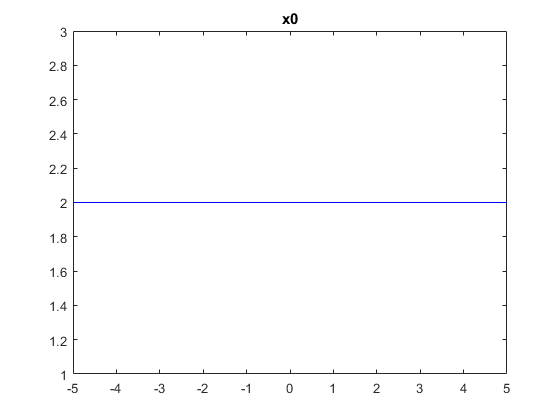

x0 = 2*ones(1,N);

plot(t, x0, 'b-');
title('x0');

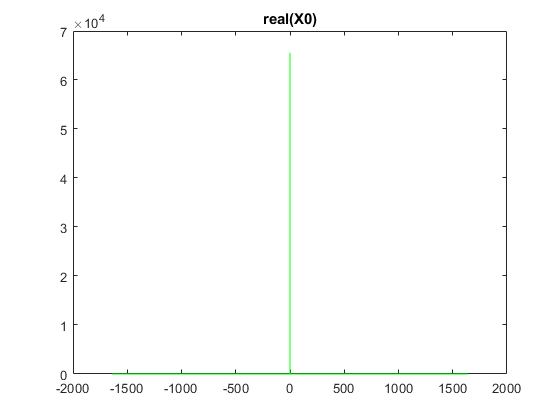

plot(f, real(tfour(x0)), 'g-');
title('real(X0)');

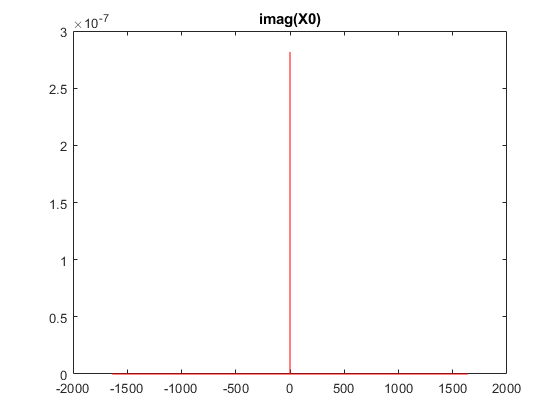

plot(f, imag(tfour(x0)), 'r-');
title('imag(X0)');

Cosinus

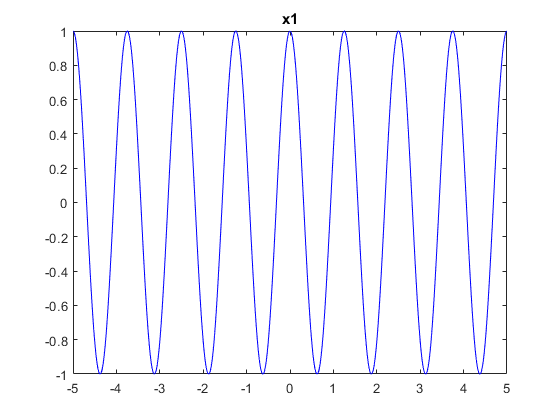

x1 = cos(2*pi*0.8*t);

plot(t, x1, 'b-')
title('x1')

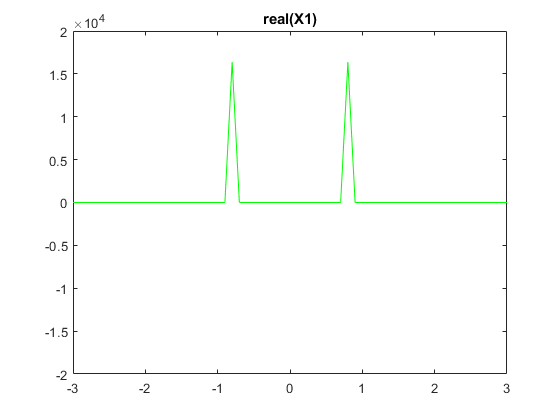

plot(f, real(tfour(x1)), 'g-')
title('real(X1)')
xlim([-3 3])
ylim([-20e3 20e3])

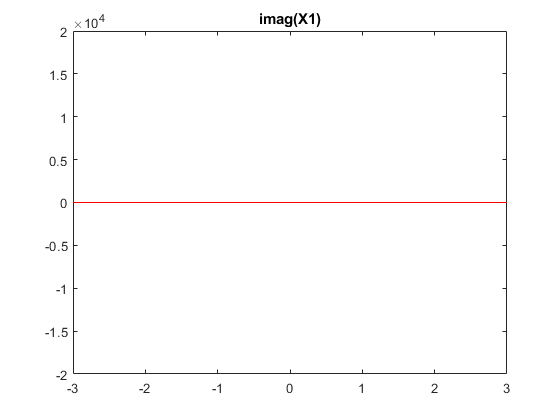

plot(f, imag(tfour(x1)), 'r-')
title('imag(X1)')
xlim([-3 3])
ylim([-20e3 20e3])

Sinus

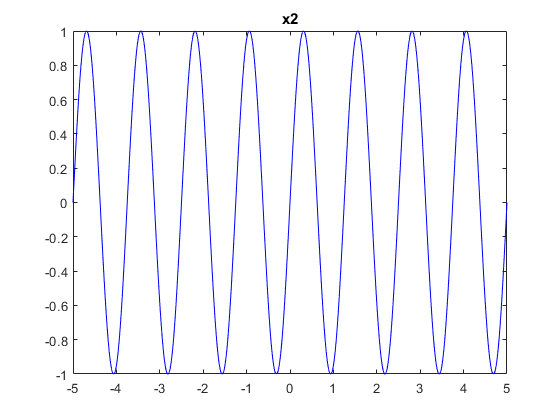

x2 = sin(2*pi*0.8*t);

plot(t, x2, 'b-');
title('x2');

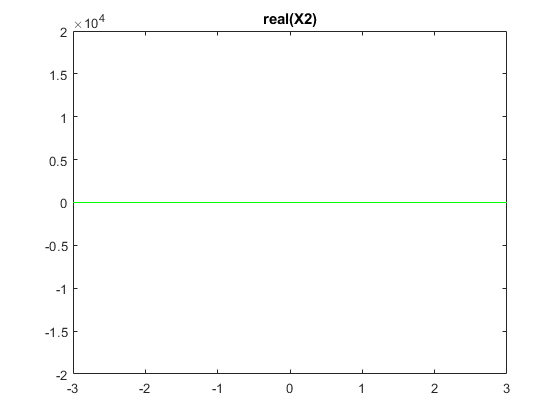

plot(f, real(tfour(x2)), 'g-');
title('real(X2)');
xlim([-3 3])
ylim([-20e3 20e3])

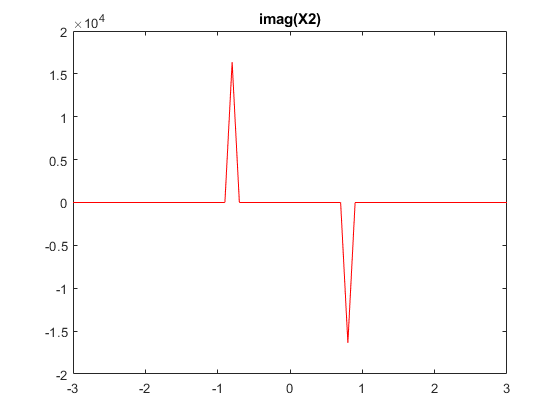

plot(f, imag(tfour(x2)), 'r-');
title('imag(X2)');
xlim([-3 3])
ylim([-20e3 20e3])

Dirac

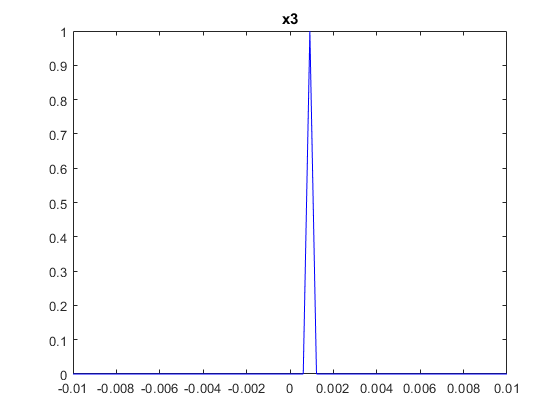

x3 = zeros(1,N);
x3(offset(0.001)) = 1;

plot(t, x3, 'b-')
title('x3')
xlim([-0.01 0.01])

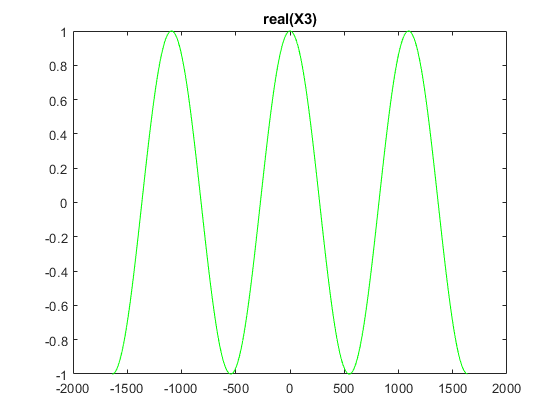

plot(f, real(tfour(x3)), 'g-')
title('real(X3)')

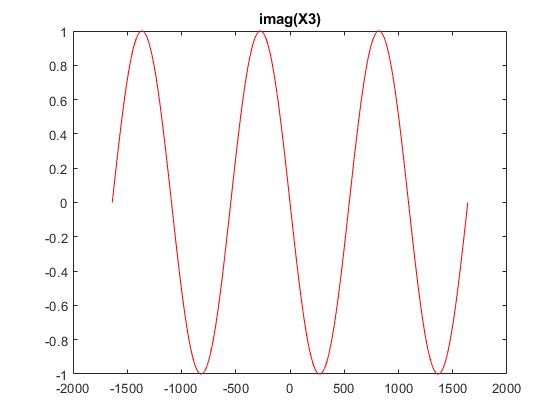

plot(f, imag(tfour(x3)), 'r-')
title('imag(X3)')

Complex exponential

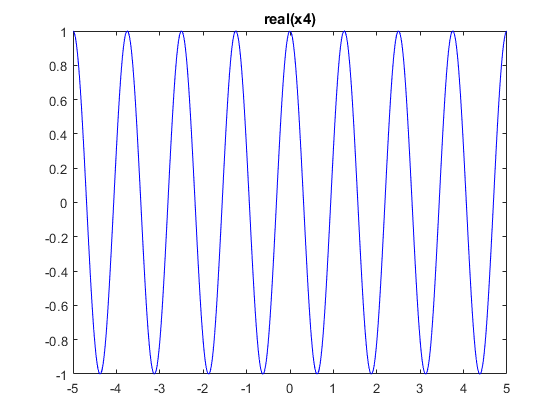

x4 = exp(i*2*pi*0.8*t);

%x4
plot(t, real(x4), 'b-')
title('real(x4)')

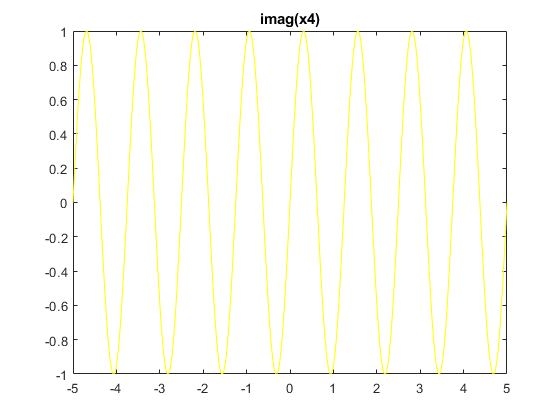

plot(t, imag(x4), 'y-')
title('imag(x4)')

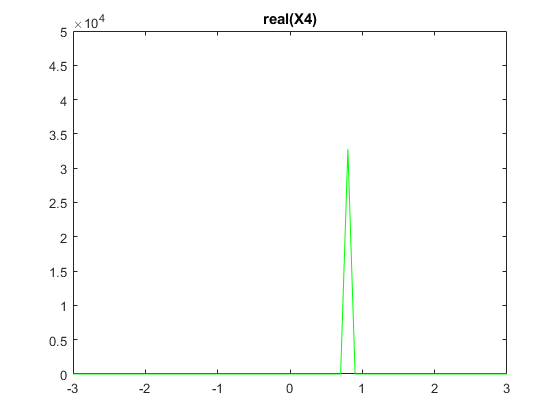

plot(f, real(tfour(x4)), 'g-')
title('real(X4)')
xlim([-3 3])
ylim([0 5e4])

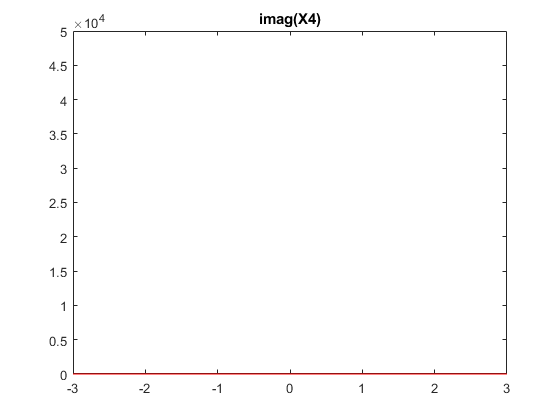

plot(f, imag(tfour(x4)), 'r-')
title('imag(X4)')
xlim([-3 3])
ylim([0 5e4])

Rect

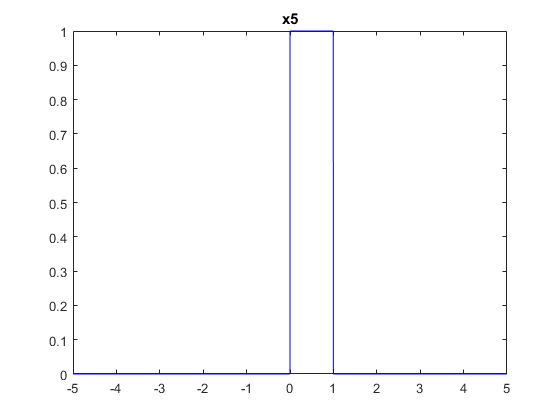

x5 = 0 <= t & t <= 1; 

plot(t, x5, 'b-')
title('x5')

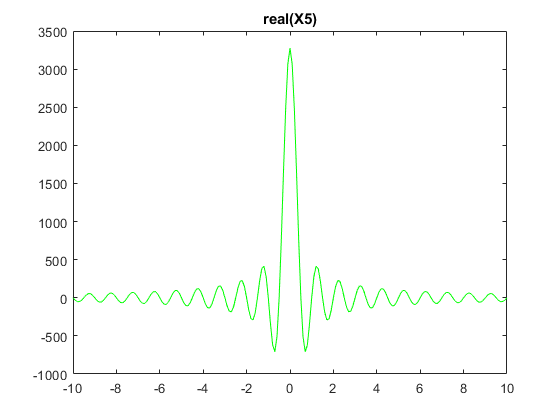

plot(f, real(tfour(x5)), 'g-')
title('real(X5)')
xlim([-10 10])

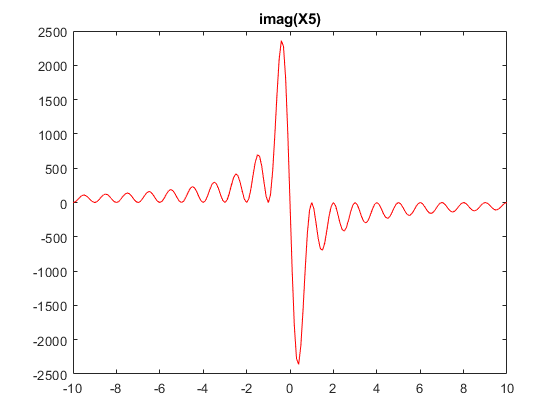

plot(f, imag(tfour(x5)), 'r-')
title('imag(X5)')
xlim([-10 10])

Gausian

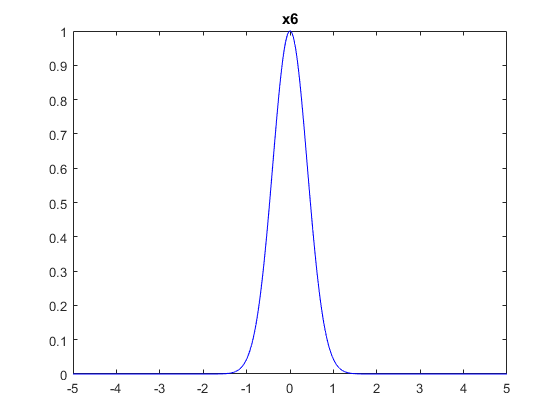

x6 = exp(-pi*t.^2);

plot(t, x6, 'b-')
title('x6')

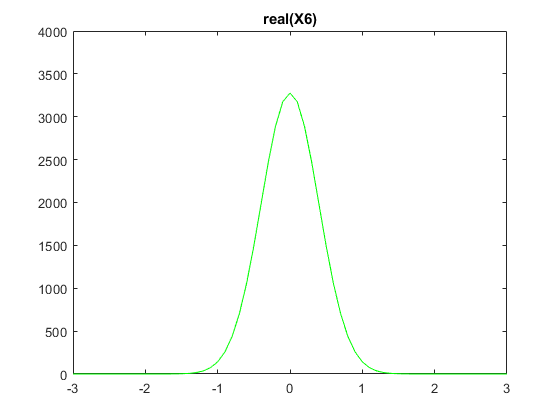

plot(f, real(tfour(x6)), 'g-')
title('real(X6)')
xlim([-3 3])
ylim([0 4e3])

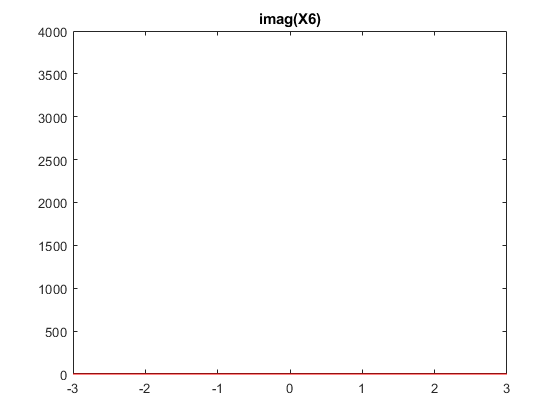

plot(f, imag(tfour(x6)), 'r-')
title('imag(X6)')
xlim([-3 3])
ylim([0 4e3])

Pour x0 : aucune observation particulière

Pour x1 : deux Diracs positifs, un en f, un en -f

Pour x2 : deux Diracs, un en f (positif), un en -f (negatif)

Pour x3 : l'allure du spectre dépend de delta t, avec delta t = 0 on obtient une gaussienne, sinon, on obtient un sinus de période très petite

Pour x4 : exponentielle complexe donc échantillonnage comprend des valeurs à la fois réelles et imaginaires, et son spectre est un Dirac en 0

Pour x6 : spectre est un sinc

Pour x6 : on obtient une gaussienne

#### **4.** echantillonnage des fonctions sur un nombre NON entier et un exemple

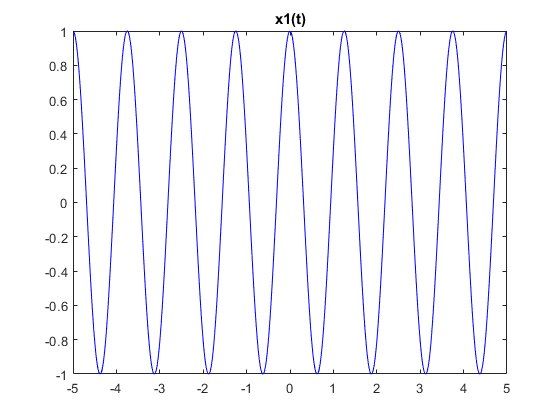

% avec un nombre non entier
x1 = cos(2*pi*0.8*t);

plot(t, x1, 'b-');
title('x1(t)');

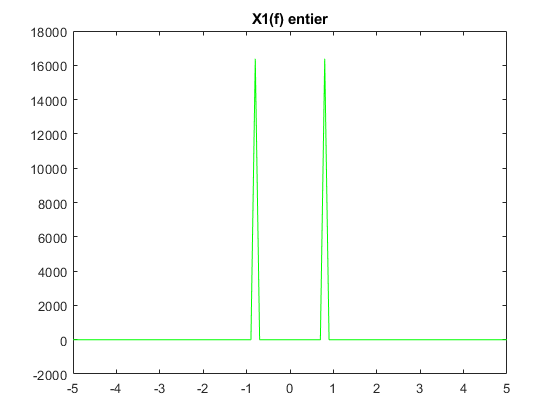

plot(f, real(tfour(x1)), 'g-');
title('X1(f) entier');
xlim([-5 5]);

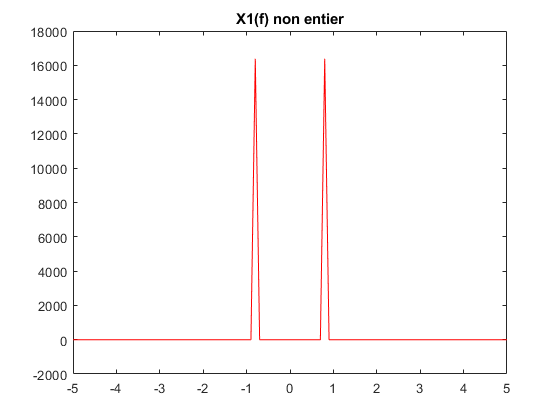


% update du nombre non entier
N = 32768.5;
Te = (b-a)/N;
fe = 1/Te;
t = linspace(a, b-Te, N);
f = linspace(-fe/2, fe/2 - fe/N, N);
x1 = cos(2*pi*0.8*t);

plot(f, real(tfour(x1)), 'r-');
title('X1(f) non entier');
xlim([-5 5]);

Avec un nombre non entier, il y a des anomalies dans le calcul de la transformée de fourier

#### **5.** tfourinv(x) pour récupérer le signal d'origine : 

en bleu le signal (sin, en rouge, la transformée de fourier du signal (sin), en vert l'inverse de la transformée de fourier, qui équivaut donc au signal d'origine (sin)

% on remet N à un nombre entier
N = 32768;
Te = (b-a)/N;
fe = 1/Te;
t = linspace(a, b-Te, N);
f = linspace(-fe/2, fe/2 - fe/N, N);
x2 = sin(2*pi*0.8*t);

plot (f, imag(tfour(x2)), 'r-');
title('imag(X2)');
xlim([-3 3]);

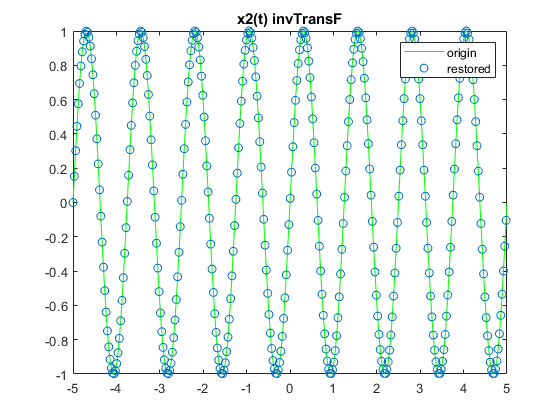

figure()
plot(t, x2, 'g-');
title('x2(t) origine');
hold on
plot(gca(), t, real(tfourinv(tfour(x2))), 'o','MarkerIndices',1:100:length(t))
title('x2(t) invTransF')
legend('origin', 'restored')
hold off

#### **6.** version périodique de x5

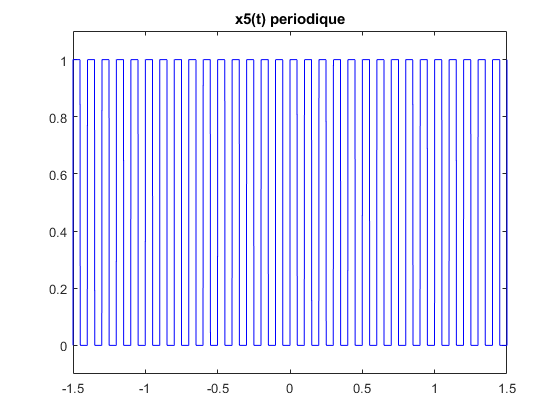

% creation de la fonction x5_bis
plot(t, x5_bis(t), 'b-');
title('x5(t) periodique');
xlim([-1.5 1.5]);
ylim([-0.1 1.1]);

#### **7.** x6 est une gaussienne, calcul de sa transformée de fourier theorique :

F(w) = exp(-(w)^2 / 4*pi))

Vérification sur les graphiques :

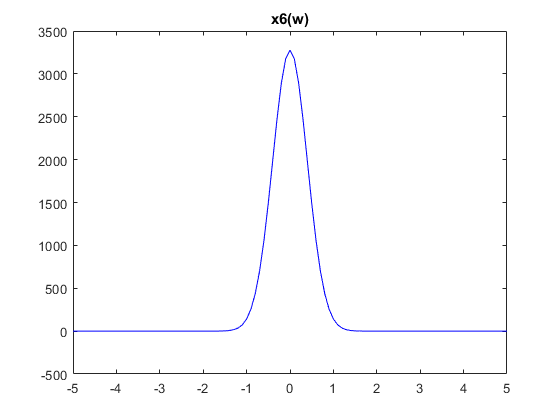

x6_theo = exp(-w.*w/4*pi);
plot(w, real(tfour(x6)), 'b-');
title('x6(w)');
xlim([-5 5]);

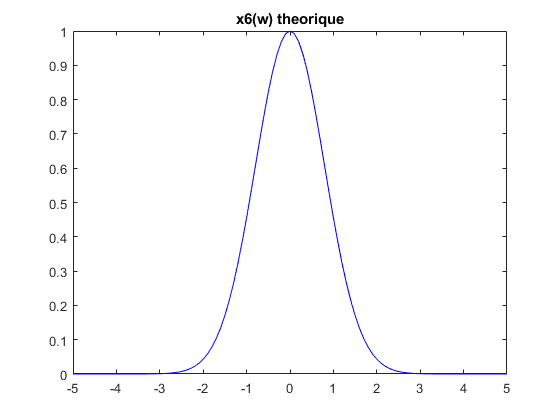

plot(w, x6_theo, 'b-');
title('x6(w) theorique');
xlim([-5 5]);

On retrouve bien la même chose (une gaussienne), mais avec un coefficient de proportionnalité.

**II - echantillonnage et aliasing**

**1.** g est une somme de 4 sinus (3 ≠ sinus) et on a remarqué plus haut avec x2 qu'une fonction sinus a deux diracs : un en (f+delta f) et un en -(f+delta f)

Ainsi, on peut s'attendre à avoir 2 * 3 = 6 diracs differents pour la fonction g

Avec un delta f = 50 :

pour g800 : en -900 ,-850, -800, 800, 850, 900 Hz

pour g2400 : en -2500, -2450, -2400, 2400, 2450, 2500 Hz

**2.** echantillonnage de g800 et g2400 + observations par rapport à la théorie

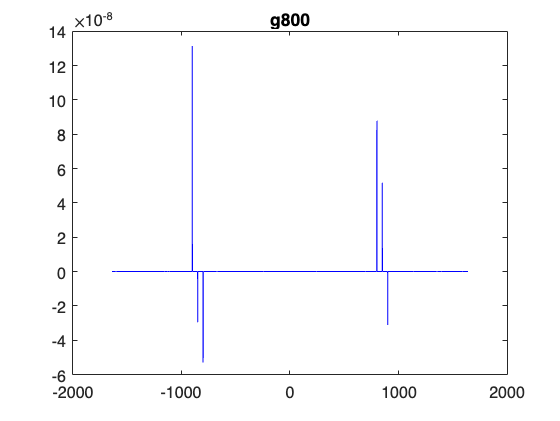

N = 32768;
a = -5;
b = 5;
Te = (b-a)/N;
fe = 1/Te;
t = linspace(a, b-Te, N);
w = linspace(-fe/2, fe/2 - fe/N, N);

f1 = 800;
f2 = 2400;

g800 = sin(2*pi*f1*t) + sin(2*pi*(f1+50)*t) - 2*sin(2*pi*(f1+2*50)*t);
g2400 = sin(2*pi*f2*t) + sin(2*pi*(f2+50)*t) - 2*sin(2*pi*(f2+2*50)*t);

plot(w, real(tfour(g800)), 'b-');
title('g800');

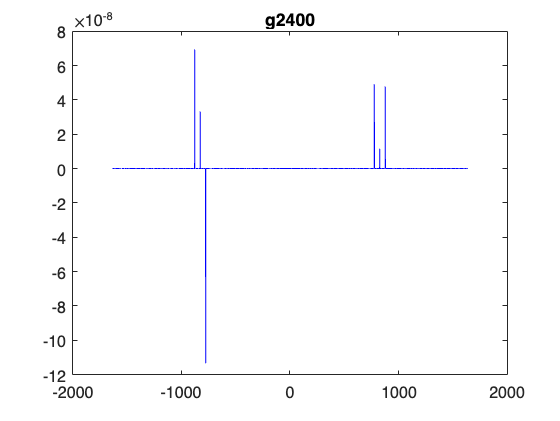

plot(w, real(tfour(g2400)), 'b-');
title('g2400');

pour g800 : observations conformes à la théorie

pour g2400 : diracs à -876, -827, -777, 777, 827 et 876

**3.** pour les valeurs positives de f suivantes on obtient un simple sinus :

f = n*fe - delta t = n*fe - 50

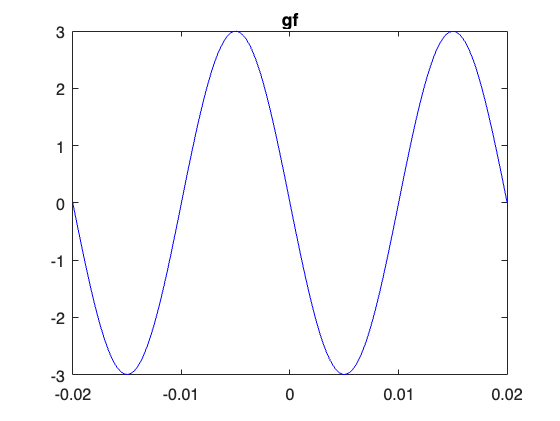

n = 1;
f = n*fe - 50;
gf = sin(2*pi*f*t) + sin(2*pi*(f+50)*t) - 2*sin(2*pi*(f+2*50)*t);

plot(t, real(gf), 'b-');
title('gf');
xlim([-0.02 0.02]);

On obtient un sinus de fréquence 0.02 = 4 * delta T

**III - transmission par modulation d'amplitude**

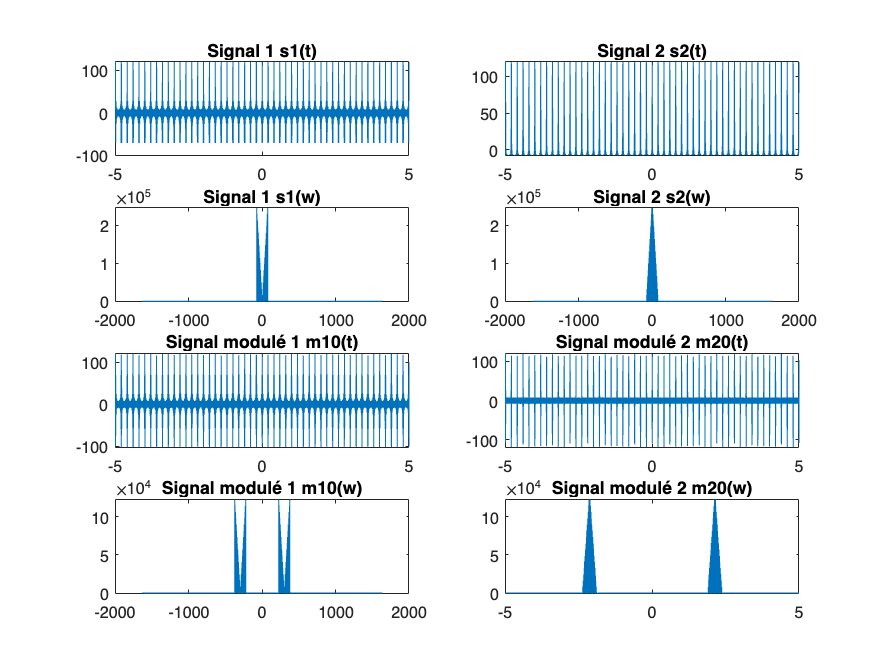

N = 32768;
a = -5;
b = 5;
Te = (b-a)/N;
fe = 1/Te;
t = linspace(a, b-Te, N);             % temporel
w = linspace(-fe/2, fe/2 - fe/N, N);  % frequentiel
f1 = 300;                             % frequence de la porteuse 1
f2 = 700;                             % frequence de la porteuse 2

% signaux à transmettre
s1 = zeros(1,N);
s2 = zeros(1,N);

% signaux modules
m10 = zeros(1,N);
m20 = zeros(1,N);
m = zeros(1,N);

% signaux demodules
d10 = zeros(1,N);
d20 = zeros(1,N);

% signaux decryptes puis filtres
s10 = zeros(1,N);
s20 = zeros(1,N);



% creation des signaux
for i = 1 : N
    for n = 1 : 15
        s1(i) = s1(i) + n*cos(2*pi*5*n*t(i));
        s2(i) = s2(i) + (16-n)*cos(2*pi*5*n*t(i));
    end
end

% modulation des signaux + demodulation
for i = 1 : N
    m10(i) = s1(i) * cos(2*pi*f1*t(i));
    m20(i) = s2(i) * cos(2*pi*f2*t(i));
    m(i) = m10(i) + m20(i);

    % démodulation
    d10(i) = m(i) * cos(2*pi*f1*t(i)); 
    d20(i) = m(i) * cos(2*pi*f2*t(i)); 
end

% filtration des signaux (traitement du signal)
s10 = tfour(d10);
s20 = tfour(d20);
figure;
rect = w <= f1/2 & w >= -f1/2;
for i = 1 : N
    s10(i) = s10(i) * rect(i);
    s20(i) = s20(i) * rect(i);
end




% affichage
% signaux originaux + modulés (t et w)
figure;
subplot(4,2,1);
plot (t, s1);
title('Signal 1 s1(t)');
subplot(4,2,3);
plot (w, real(tfour(s1)));
title('Signal 1 s1(w)');
subplot(4,2,5);
plot (t, m10);
title('Signal modulé 1 m10(t)');
subplot(4,2,7);
plot (w, real(tfour(m10)));
title('Signal modulé 1 m10(w)');

subplot(4,2,2);
plot (t, s2);
title('Signal 2 s2(t)');
subplot(4,2,4);
plot (w, real(tfour(s2)));
title('Signal 2 s2(w)');
subplot(4,2,6);
plot (t, m20);
title('Signal modulé 2 m20(t)');
subplot(4,2,8);
plot (w, real(tfour(m20)));
title('Signal modulé 2 m20(w)');

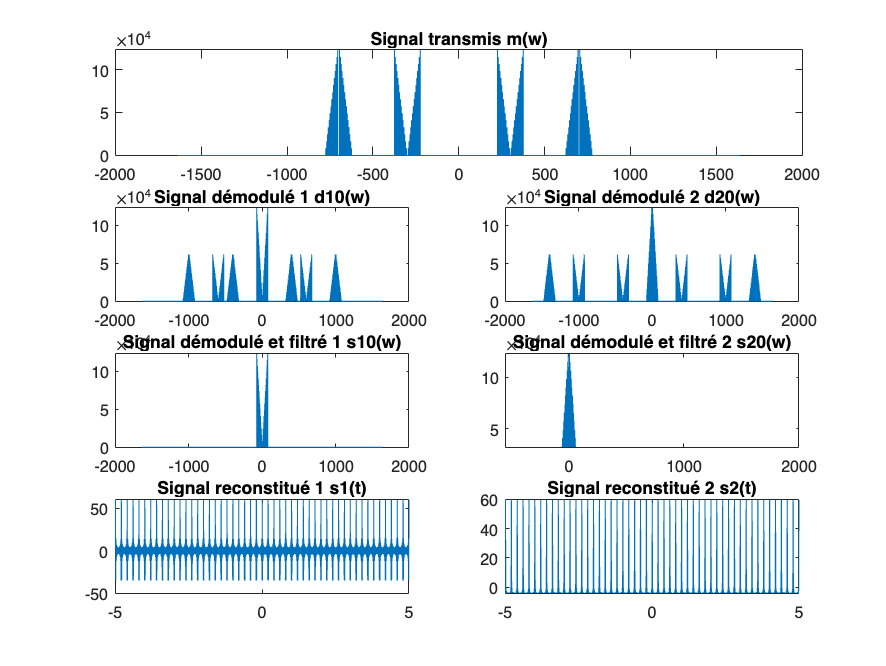



% signal transmis (somme) + signaux démodulés, filtrés (w) 
% et reconstitués (t)
figure;
subplot(4,2,[1 2]);
plot(w, real(tfour(m)));
title('Signal transmis m(w)');

subplot(4,2,3);
plot (w, real(tfour(d10)));
title('Signal démodulé 1 d10(w)');
subplot(4,2,5);
plot(w, real(s10));
title('Signal démodulé et filtré 1 s10(w)');
subplot(4,2,7);
plot(t,real(tfourinv(s10)));
title('Signal reconstitué 1 s1(t)');

subplot(4,2,4);
plot (w, real(tfour(d20)));
title('Signal démodulé 2 d20(w)');
subplot(4,2,6);
plot (w, real(s20));
title('Signal démodulé et filtré 2 s20(w)');
subplot(4,2,8);
plot(t,real(tfourinv(s20)));
title('Signal reconstitué 2 s2(t)');

**1.** conséquence de la modulation sur les signaux s1(t) et s2(t) : permet d'espacer le signal dans sa représentation fréquentielle (écarter du 0 dans notre cas), ce qui est indispensable lorsque plusieurs signaux sont diffusés sur le même canal

**2.** la démodulation sur un signal modulé permet de retrouver le signal original si(t)

**3.** précautions à prendre pour pouvoir diffuser plusieurs signaux sur un même canal sans qu'ils ne se mélangent, et qu'il soit possible de les récupérer au moment de la réception : il faut que l'écart entre les deux porteuses (les signaux modulés mi(t)) en terme de fréquence soit assez important pour qu'elles ne se chevauchent pas et ainsi éviter une collision lors de la somme des signaux modulés (m(t)) et donc lors de la démodulation

**4.** pour extraire un des signaux d'origine à partir du signal démodulé, il faut traiter le signal par un filtre passe bas, puis appliquer la transformation de fourier inverse pour retrouver le signal d'origine si(t)

**IV - filtrages**

Construction des fonctions de transfert de filtres à partir de la gaussienne de la partie d'avant

on trouve PB avec le spectre spatial de l'image, pour l'avoir : on floute l'image, on fait un truc, et PB apparait au dénominateur

On applique le filtre à l'image, et on retrouve une image restaurée :)